# Examples of Noise Maskers

% addpath('C:\...\')

clear all; clc;

fileName = 'ENG_MA_F1_0007.wav';
BWD = which(fileName);
i = find(filesep==BWD);
BWD = BWD(1:i(end));

[S,fsS] = audioread([BWD fileName]);

brks = 0.5:7:36;
sent = cell([length(brks)-1 1]);

for i = 1:length(brks)-1
    sent{i} = S(fsS*brks(i):fsS*brks(i+1));
end

NyqFreq = fsS/2;            % fs = 2kHz; Nyquist freq. = 1 kHz
Wn = [50 5000]/NyqFreq;     % Normalised band-pass cut-off frequencies (50-5000Hz)
[b,a] = butter(6/2,Wn);     % create foreward and backward filter; 6th order            % requires the Signal Processing Toolbox
S_filt = filtfilt(b,a,S);   % use fvtool(b,a) if you want to visualise the filter

brks = 0.5:7:35.5;
sent_filt = cell([length(brks)-1 1]);

for i = 1:length(brks)-1
    sent_filt{i} = S_filt(fsS*brks(i):fsS*brks(i+1)-1);
end

parameter = [];
parameter.fsAudio = fsS;
parameter.zeroPad = fsS/10;
[spec,f,t] = stft(sent{1},parameter);                              % requires the MATLAB_TSM-Toolbox_2.02

whiteNoise = cell([length(brks)-1 1]);
whiteNoise_filt = cell([length(brks)-1 1]);

for i = 1:length(brks)-1
    rng('default');
    rng(i, 'Twister');
    whiteNoise{i} = randn(1, size(sent_filt{i},1));
    whiteNoise_filt{i} = filtfilt(b,a,whiteNoise{i});
end
rng('default');

RMS_N = NaN([length(brks)-1 1]);
RMS_S = NaN([length(brks)-1 1]);
for i = 1:length(brks)-1
    RMS_N(i) = rms(whiteNoise_filt{i});
    if i == 2
        RMS_S(i) = rms(sent_filt{i}(1:110000));
    elseif i == 3
        RMS_S(i) = rms(sent_filt{i}(1:115000));
    elseif i == 4
        RMS_S(i) = rms(sent_filt{i}(1:105000));
    elseif i == 5
        RMS_S(i) = rms(sent_filt{i}(1:100000));
    else
        RMS_S(i) = rms(sent_filt{i});
    end
end
new_RMS_N = mean(RMS_S);
ScaleFact = RMS_N./new_RMS_N;
for i = 1:length(brks)-1
    whiteNoise_filt{i} = whiteNoise_filt{i}./ScaleFact(i);
end


% now we add up S & N and we equalize the rms of the SiN snippets
target_dB_SNR = -10:5:10;
target_lin_SNR = 10.^(target_dB_SNR/20);

scaled_S = cell([length(brks)-1 length(target_dB_SNR)]);
SiWN = cell([length(brks)-1 length(target_dB_SNR)]);
SiWN_scaled = cell([length(brks)-1 length(target_dB_SNR)]);

for i = 1:length(brks)-1
    RMS_S = rms(sent_filt{i});
    actual_dB_SNR = 20*log10(RMS_S/new_RMS_N);
    actual_lin_SNR = 10^(actual_dB_SNR/20);
    for j = 1:length(target_dB_SNR)
        scaleFact_S = target_lin_SNR(j)/actual_lin_SNR;  
            % if < 1 will reduce speech rms,
            % if > 1 will increase speech rms
        scaled_S{i,j} = sent_filt{i} * scaleFact_S;
        SiWN{i,j} = whiteNoise_filt{i}' + scaled_S{i,j};
        SiWN_scaled{i,j} = SiWN{i,j} ./ (rms(SiWN{i,j})./new_RMS_N);
        % add ramps (10ms) to avoid annoying auditory glitches
        SiWN{i,j}(1:fsS/100) = SiWN{i,j}(1:fsS/100) .* linspace(0,1,fsS/100)';
        SiWN{i,j}(end-fsS/100+1:end) = SiWN{i,j}(end-fsS/100+1:end) .* linspace(1,0,fsS/100)';
        SiWN_scaled{i,j}(1:fsS/100) = SiWN_scaled{i,j}(1:fsS/100) .* linspace(0,1,fsS/100)';
        SiWN_scaled{i,j}(end-fsS/100+1:end) = SiWN_scaled{i,j}(end-fsS/100+1:end) .* linspace(1,0,fsS/100)';
    end
end

## SiWN: no adjustment for intensiy (SNR confounded by RMS)

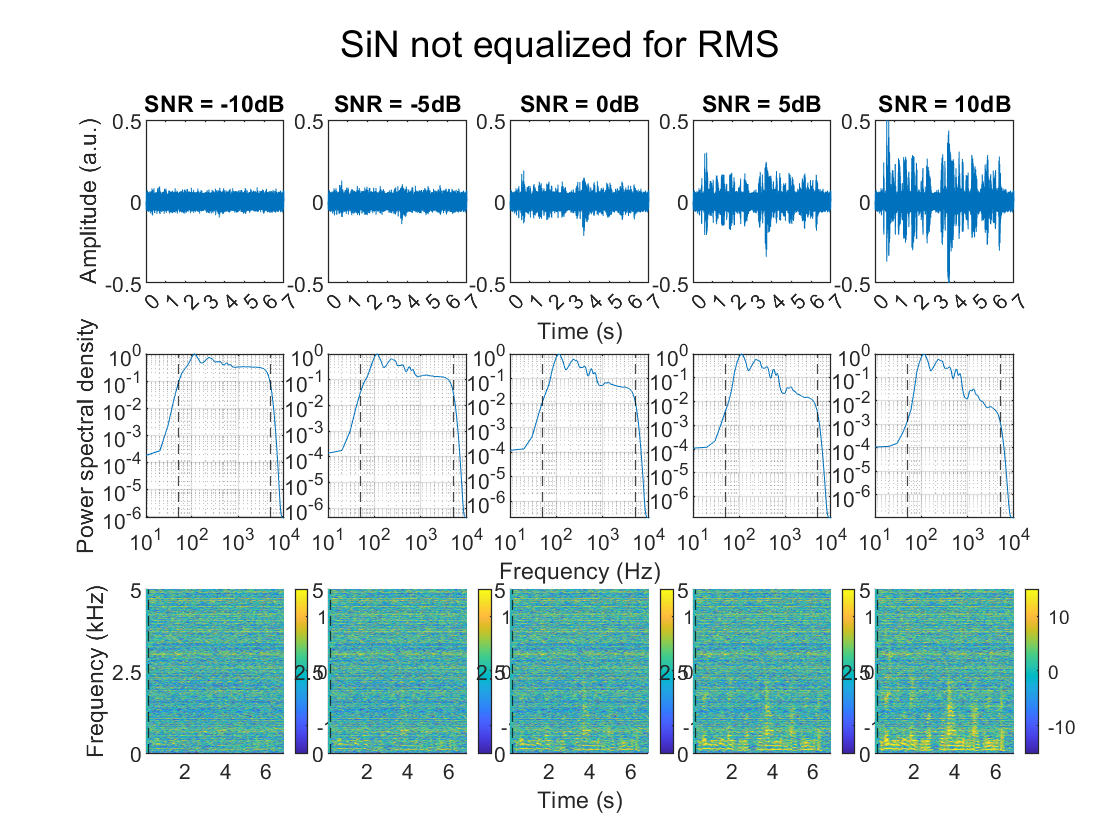

figure;
row = 1;            % waveform:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(3,5,p);
    plot(SiWN{1,j});
    xlim([0 fsS*7]);
    xticks(0:fsS:fsS*7);
    xticklabels(0:7);
    xtickangle(45);
    ylim([-0.5 0.5]);
    title(['SNR = ' num2str(target_dB_SNR(j)) 'dB']);
    if j == 1
        ylabel('Amplitude (a.u.)');
    end
    if j == 3
        xlabel('Time (s)');
    end
end

row = 2;            % LTAS:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(3,5,p);
    if j == 1
        ltas_TH(SiWN{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'yL',1,'xTickL',[1e1 1e2 1e3 1e4],'yTickL',flip([10^0 10^-1 10^-2 10^-3 10^-4 10^-5 10^-6 10^-7]));
    elseif j == 3
        ltas_TH(SiWN{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'xL',1,'xTickL',[1e1 1e2 1e3 1e4],'yTickL',flip([10^0 10^-1 10^-2 10^-3 10^-4 10^-5 10^-6 10^-7]));
    else
        ltas_TH(SiWN{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'xTickL',[1e1 1e2 1e3 1e4],'yTickL',flip([10^0 10^-1 10^-2 10^-3 10^-4 10^-5 10^-6 10^-7]));
    end
    xline(50, '--k'); xline(5000, '--k'); hold off;
end

row = 3;            % Spectrogram
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    parameter = [];
    parameter.fsAudio = fsS;
    parameter.zeroPad = fsS/10;
    spec_SiWN = stft(SiWN{1,j},parameter);
    
    basl_IDX = 2:3;
    baseline = mean(abs(spec_SiWN(:,basl_IDX)),2);
    dB_pow = 10*log10(abs(spec_SiWN)./baseline);
    
    subplot(3,5,p);
    surf(t(2:end-3),f(1:round(length(f)/2)+1),dB_pow(1:round(length(f)/2)+1,2:end-3));
    hold on; set(gcf,'renderer','zbuffer');
    shading interp; view(0,90); axis tight;
    xline(t(basl_IDX(end)), '--k');
    yticks([0 2500 5000]);
    yticklabels(yticks/1000);
    if j == 1
        ylabel('Frequency (kHz)')
    end
    if j == 3
        xlabel('Time (s)');
    end
    colorbar;
    caxis manual;
    caxis([-15 15]);
end

suptitle('SiN not equalized for RMS');

## SiWN: adjusted for intensiy

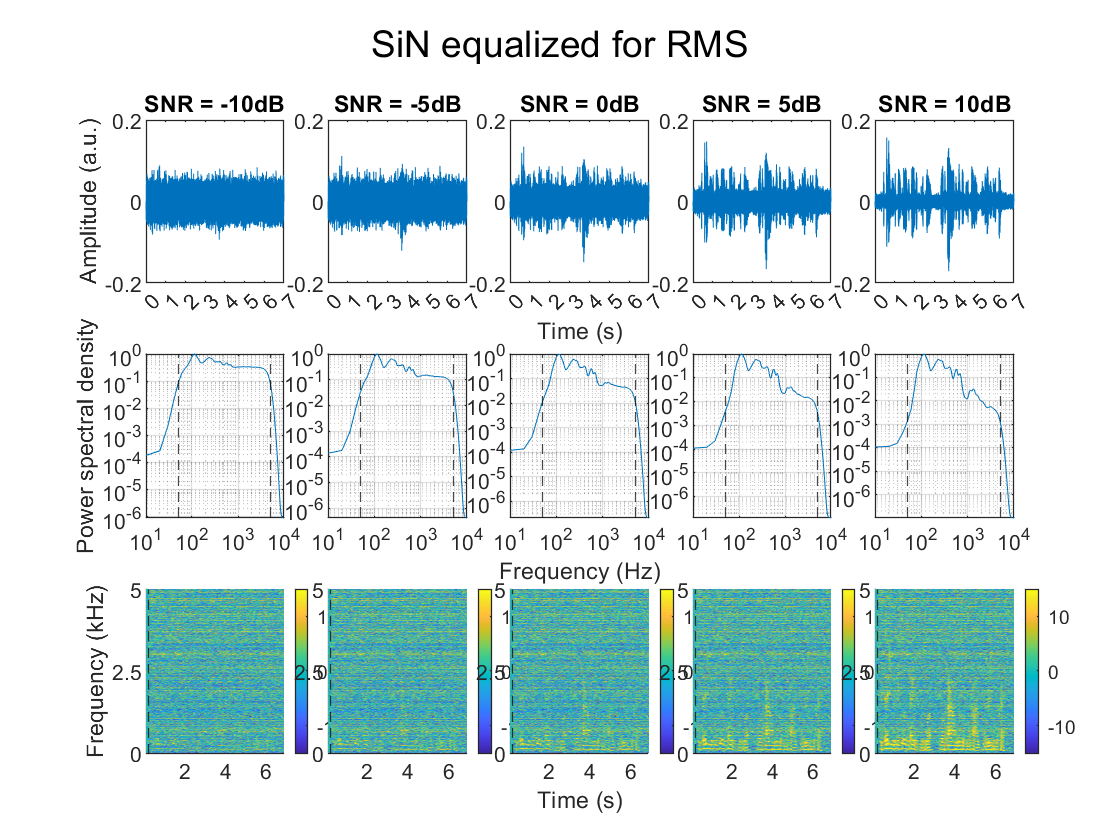

figure;
row = 1;            % waveform:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(3,5,p);
    plot(SiWN_scaled{1,j});
    xlim([0 fsS*7]);
    xticks(0:fsS:fsS*7);
    xticklabels(0:7);
    xtickangle(45);
    ylim([-0.2 0.2]);
    title(['SNR = ' num2str(target_dB_SNR(j)) 'dB']);
    if j == 1
        ylabel('Amplitude (a.u.)');
    end
    if j == 3
        xlabel('Time (s)');
    end
end

row = 2;            % LTAS:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(3,5,p);
    if j == 1
        ltas_TH(SiWN_scaled{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'yL',1,'xTickL',[1e1 1e2 1e3 1e4],'yTickL',flip([10^0 10^-1 10^-2 10^-3 10^-4 10^-5 10^-6 10^-7]));
    elseif j == 3
        ltas_TH(SiWN_scaled{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'xL',1,'xTickL',[1e1 1e2 1e3 1e4],'yTickL',flip([10^0 10^-1 10^-2 10^-3 10^-4 10^-5 10^-6 10^-7]));
    else
        ltas_TH(SiWN_scaled{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'xTickL',[1e1 1e2 1e3 1e4],'yTickL',flip([10^0 10^-1 10^-2 10^-3 10^-4 10^-5 10^-6 10^-7]));
    end
    xline(50, '--k'); xline(5000, '--k'); hold off;
end

row = 3;            % Spectrogram
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    parameter = [];
    parameter.fsAudio = fsS;
    parameter.zeroPad = fsS/10;
    spec_SiWN = stft(SiWN_scaled{1,j},parameter);
    
    basl_IDX = 2:3;
    baseline = mean(abs(spec_SiWN(:,basl_IDX)),2);
    dB_pow = 10*log10(abs(spec_SiWN)./baseline);
    
    subplot(3,5,p);
    surf(t(2:end-3),f(1:round(length(f)/2)+1),dB_pow(1:round(length(f)/2)+1,2:end-3));
    hold on; set(gcf,'renderer','zbuffer');
    shading interp; view(0,90); axis tight;
    xline(t(basl_IDX(end)), '--k');
    yticks([0 2500 5000]);
    yticklabels(yticks/1000);
    if j == 1
        ylabel('Frequency (kHz)')
    end
    if j == 3
        xlabel('Time (s)');
    end
    colorbar;
    caxis manual;
    caxis([-15 15]);
end

suptitle('SiN equalized for RMS');


% clear whiteNoise whiteNoise_filt SiWN SiWN_filt